# Filtro espectral

clear;
load tseries_test.mat;
[NT,tserie_size] = size(tseries_test);

#### Cargar una serie de tiempo de prueba

Fs = 23;              % Frecuencia de muestra (muestras por unidad de tiempo o espacio)               
T = 1/Fs;             % espacio por muestra    
L = tserie_size;      % Length of signal
t = (0:L-1)*T;        % Time vector

%id = 10;
id =4;
S  = tseries_test(id,:);

#### Agregar huecos de manera artificial

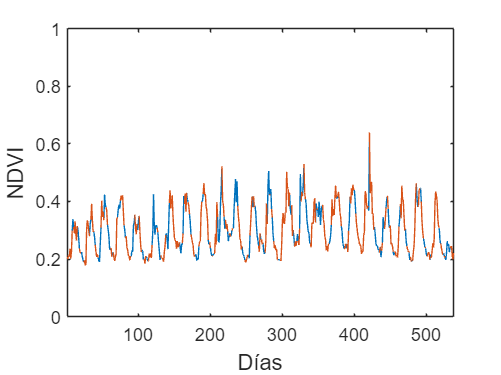

%id = 10;
huecos =124;
nhuecos = 0;
Snan = S;
while (nhuecos<huecos)
    x = randi([1 tserie_size]);
    if( ~isnan(Snan(x)) )
        Snan(x)=nan;
        nhuecos=nhuecos+1;
    end
end

%%% mostrar la serie original y la serie artifical con huecos
figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snan);
hold off;


mean_snan = mean(Snan,"all","omitnan");
disp("PROMEDIO: "+mean_snan);

PROMEDIO: 0.30092


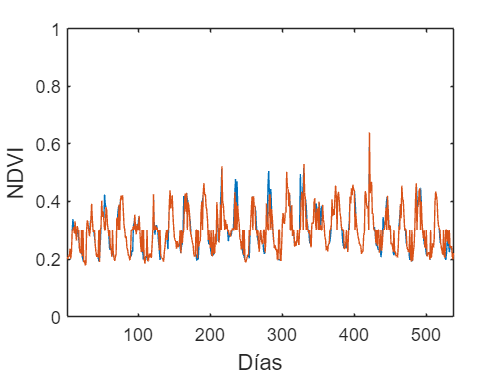

Snan( isnan(Snan))=mean_snan;

figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snan);
hold off;

## Espectro de amplitud de la serie

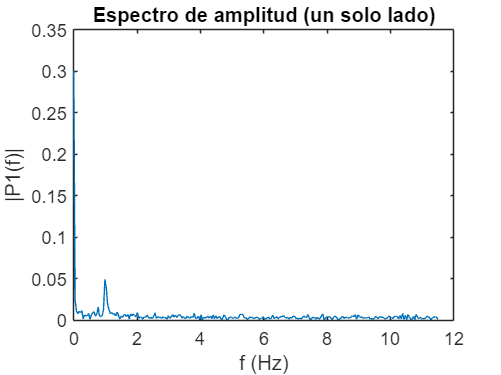

Y = fft(Snan);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure;
plot(f,P1) 
title("Espectro de amplitud (un solo lado)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

## Suavizar mediante Frecuencia mayor amplitud

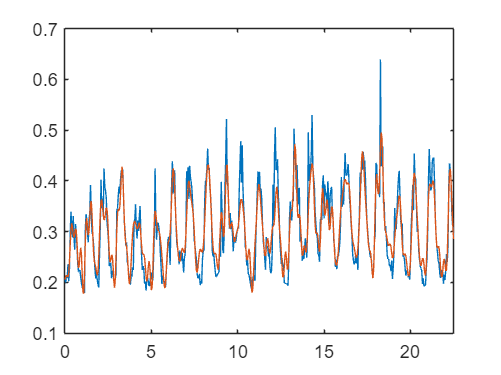

mit = L/2;

rng = 177;
Yf = Y;

Yf(mit-rng+1:mit+rng+1) = 0;
Yfp = abs(Yf);

P2 = abs(Yfp/L);
P1 = P2(1:int16(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

Sf = real(ifft(Yf));
figure;
plot(t,S,t,Sf);
xlim([0 22.5]);

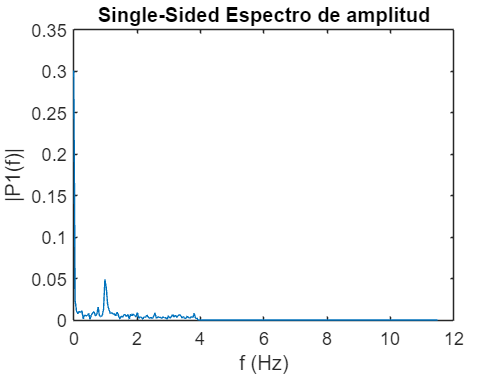


figure;
plot(f,P1) 

title("Single-Sided Espectro de amplitud")
xlabel("f (Hz)")
ylabel("|P1(f)|")